%% Parameters
sigma_T = 2.75; % Variance for temperature effect
beta0 = 0.38;   % Baseline transmission rate
k2 = 0.1;       % Steepness parameter for logistic rainfall effect

%% Randomized optimal values
T_opt = 15 + (22-15)*rand();        % Random temperature between 20-22°C
theta_opt = 80 + (140-80)*rand();   % Random rainfall between 80-140 mm


theta_mean = 110; % Mean rainfall value (fixed for this analysis)

%% Load temperature data
[fileName, filePath] = uigetfile('*.csv', 'Select the CSV file with Temperature and Rainfall Data');
if isequal(fileName, 0)
    error('No file selected. Please provide the correct file.');
else
    data = readtable(fullfile(filePath, fileName));
    disp('File successfully loaded.');
end

File successfully loaded.


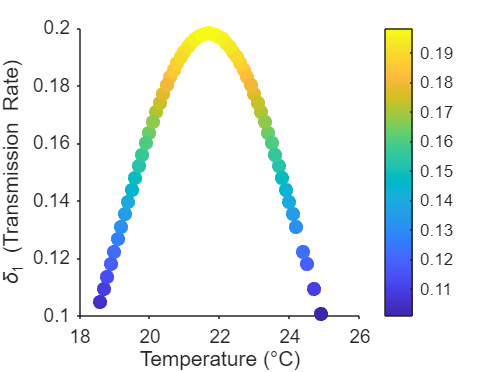


% Check if the required column exists
if ~ismember('Temperature', data.Properties.VariableNames)
    error('Dataset must contain "Temperature" column.');
end

% Extract temperature
T = data.Temperature;

%% Define beta_e as a function handle
beta_e = @(T, theta) beta0 .* exp( -((T - T_opt).^2) ./ (2*sigma_T^2) ) ...
    .* (1 ./ (1 + exp(-k2 * (theta - theta_opt))));

%% Compute beta_e vs Temperature
beta_e_values = zeros(length(T), 1);
for i = 1:length(T)
    beta_e_values(i) = beta_e(T(i), theta_mean);
end

%% Visualization 1: beta_e vs Temperature (SCATTER)
figure;
scatter(T, beta_e_values, 50, beta_e_values, 'filled');
xlabel('Temperature (°C)', 'FontName', 'Arial', 'FontWeight', 'normal');
ylabel('\delta_1 (Transmission Rate)', 'FontName', 'Arial', 'FontWeight', 'normal');
colorbar('FontName', 'Arial', 'FontWeight', 'normal');
grid off;

ax = gca;
ax.FontName = 'Arial';
ax.FontWeight = 'normal';
ax.TickDir = 'out';

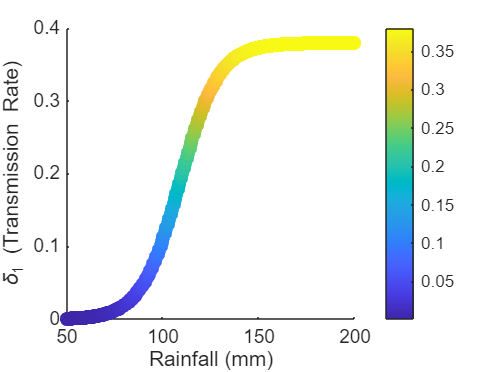

ax.Box = 'off';

%% Visualization 2: beta_e vs Rainfall (SCATTER)
theta_range = linspace(50, 200, 200); % Rainfall range
T_fixed = mean(T); % Fix temperature at dataset mean
beta_e_rainfall = beta_e(T_fixed, theta_range);

figure;
scatter(theta_range, beta_e_rainfall, 50, beta_e_rainfall, 'filled'); % Scatter plot
xlabel('Rainfall (mm)', 'FontName', 'Arial', 'FontWeight', 'normal');
ylabel('\delta_1 (Transmission Rate)', 'FontName', 'Arial', 'FontWeight', 'normal');
colorbar('FontName', 'Arial', 'FontWeight', 'normal');

%grid on;

%% Summary Statistics
disp('Summary Statistics for beta_e (Effect of Temperature):');

Summary Statistics for beta_e (Effect of Temperature):


fprintf('Randomized T_opt = %.2f °C\n', T_opt);

Randomized T_opt = 21.70 °C


fprintf('Randomized θ_opt = %.2f mm\n', theta_opt);

Randomized θ_opt = 109.12 mm


fprintf('Mean beta_e: %.2f\n', mean(beta_e_values));

Mean beta_e: 0.17


fprintf('Max beta_e: %.2f\n', max(beta_e_values));

Max beta_e: 0.20


fprintf('Min beta_e: %.2f\n', min(beta_e_values));

Min beta_e: 0.10
